De Veld, D. C. G., Witjes, M. J. H., Sterenborg, H. J. C. M., & Roodenburg, J. L. N. (2005). The status of in vivo autofluorescence spectroscopy and imaging for oral oncology. *Oral oncology*, *41*(2), 117-131.

Figure 1 - mean spectra for different tumor classifications (excluding tumors on the dorsal tongue and vermilion border of the lip)

De Veld, D. C., Skurichina, M., Witjes, M. J., Duin, R. P., Sterenborg, H. J., & Roodenburg, J. L. (2005). Autofluorescence and diffuse reflectance spectroscopy for oral oncology. Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery, 36(5), 356-364.

This paper only shows the results of a benign lesion (Figure 2)

ieInit;
wave = 500:600;
normWave = 520;
% fise_plotDefaults;
 

## Read the saved model fluorophores

These have no blood.  The blood will be read in during the fitting process with oeSolveBlood.

fname = fullfile(oeTongueLipRootPath,'data','savedFluorophores');
[savedFluorophores,~,comment] = ieReadSpectra(fname,wave);
%{
plotRadiance(wave,savedFluorophores);
legend(comment.names);
%}

## Read the external data

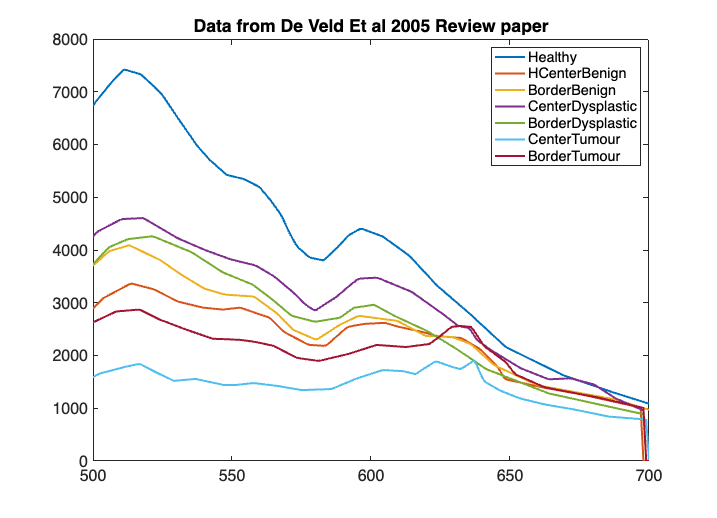

Unrecognized function or variable 'TongueBetz'.


BorderBenign = ieReadSpectra('BorderBenign.mat',wave);
BorderDysplastic = ieReadSpectra('BorderDysplastic.mat',wave);
BorderTumour = ieReadSpectra('BorderTumour.mat',wave);
CenterBenign = ieReadSpectra('CenterBenign.mat',wave);
CenterDysplastic = ieReadSpectra('CenterDysplastic.mat',wave);
CenterTumour = ieReadSpectra('CenterTumour.mat',wave);
Healthy = ieReadSpectra('Healthy.mat',wave);

ieFigure; 
plot(wave,Healthy); hold on;
plot(wave,CenterBenign);
plot(wave,BorderBenign);
plot(wave,CenterDysplastic);
plot(wave,BorderDysplastic);
plot(wave,CenterTumour);
plot(wave,BorderTumour); 
title('Data from De Veld Et al 2005 Review paper');
legend('Healthy','CenterBenign','BorderBenign','CenterDysplastic','BorderDysplastic','CenterTumour','BorderTumour'); 
lines = findall(gca, 'Type', 'Line');
set(lines,'LineWidth', 2);
set(gca,'fontsize',16); set(gca, 'FontName', 'Helvetica');


BorderBenign = BorderBenign/BorderBenign(wave == 520);
BorderDysplastic= BorderDysplastic/BorderDysplastic(wave == 520);
BorderTumour = BorderTumour/BorderTumour(wave == 520);
CenterBenign = CenterBenign/CenterBenign(wave == 520);
BorderBenign = BorderBenign/BorderBenign(wave == 520);
CenterDysplastic = CenterDysplastic/CenterDysplastic(wave == 520);
CenterTumour = CenterTumour/CenterTumour(wave == 520);
Healthy = Healthy/Healthy(wave == 520);

ieFigure; 
plot(wave,Healthy); hold on;
plot(wave,CenterBenign);
plot(wave,BorderBenign);
plot(wave,CenterDysplastic);
plot(wave,BorderDysplastic);
plot(wave,CenterTumour);
plot(wave,BorderTumour); 
title('Data from De Veld Et al 2005 Review paper');
legend('Healthy','HCenterBenign','BorderBenign','CenterDysplastic','BorderDysplastic','CenterTumour','BorderTumour'); 
lines = findall(gca, 'Type', 'Line');
set(lines, 'LineWidth', 2);
set(gca,'fontsize',16); set(gca, 'FontName', 'Helvetica');


## Fit the model to healthy tissue

[odH,weightsH,finalFluorophoresH] = oeSolveBlood(wave,Healthy,savedFluorophores);
predictedH = finalFluorophoresH*weightsH(:);
ieFigure;
plot(wave,predictedH,'k--',wave,Healthy);
grid on;
title(sprintf('Healthy (od = %.3f)',odH));
legend("predicted","Healthy");

labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odH; weightsH(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Center Tumour\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

## Fit the model to the Center Tumor

[odCT,weightsCT,finalFluorophoresCT] = oeSolveBlood(wave,CenterTumour,savedFluorophores);
predictedCT = finalFluorophoresCT*weightsCT(:);
ieFigure;
plot(wave,predictedCT,'k--',wave,CenterTumour);
grid on;
title(sprintf('Center Tumor(od = %.3f)',odCT));
legend("predicted","Center Tumor");

labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odCT; weightsCT(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Center Tumour\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

## Fit the model to the Border Tumor

[odBT,weightsBT,finalFluorophoresBT] = oeSolveBlood(wave,BorderTumour,savedFluorophores);
predictedBT = finalFluorophoresBT*weightsBT(:);
ieFigure;
plot(wave,predictedBT,'k--',wave,BorderTumour);
grid on;
title(sprintf('Border Tumour(od = %.3f)',odBT));
legend("predicted","Border Tumour");

labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odBT; weightsBT(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Center Tumour\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end


## Fit the model to the Center Dysplastic

## Fit the model to the Border Dysplastic

## Fit the model to the Center Benign

## Fit the model to the Border Benign